# ΕΡΓΑΣΤΗΡΙΑΚΟ ΜΕΡΟΣ Β) ΘΕΜΑ 4 ) 

ΟΝΟΜΑΤΕΠΩΝΥΜΟ : ΤΣΑΚΤΑΝΗΣ ΓΕΩΡΓΙΟΣ

ΕΤΟΣ : 4 

ΑΜ :1059343 

Για την επεξεργασία του βίντεο και τον χωρισμό του σε frame  και την διαχείριση του ως αρχείο χρησιμοποιήθηκε ως source ε΄τπιμη συνάρηση της matlab .

clc;
clear all;

Δημιουργείται ένας προσωρινός φάκελος εργασίς στον οποίο αποθηκεύονται οι εικόνες (frames) του βιντεο.

workingDir ='C:\Users\tsakt\OneDrive\Υπολογιστής\ECE\8o\επεξερ Εικονας\Μέρος Β-2020-2021';
mkdir(workingDir);
mkdir(workingDir,'images');

 Δημιουργείται ένας VideoReader για να διαβαστούν τα frames από τον φάκελο

shuttleVideo = VideoReader('april21.avi');

**Δημιουργία ακολουθίας εικόνων.** Παίζοντας το βιντεο και διαβάζοντας κάθε frame  σε έναν **τρισδιάστατο** πίνακα με όνομα img. Γράφεται κάθε εικόνα σε έναν φάκελο JPEG με όνομα imgN όπου το Ν είναι ο αριθμός του εκάστοτε frame.

ii = 1;
while hasFrame(shuttleVideo)
   img = readFrame(shuttleVideo);
   filename = [sprintf('%03d',ii) '.jpg'];
  
   fullname = fullfile(workingDir,'images',filename);
   imwrite(img,fullname)    % Write out to a JPEG file (img1.jpg, img2.jpg, etc.)
   ii = ii+1;
end

** Βρίσκουμε τα ονόματα  αρχείων των εικόνων**

 ετατρέπουμε  το set των εικόνων σε ένα πίνακα με 300 κελιά 

imageNames = dir(fullfile(workingDir,'images','*.jpg'));
imageNames = {imageNames.name}';

**Δημιουργείται ένα καινούριο Video με την ακολουθία εικόνων**

Κατασκευάζεται έαν `VideoWriter` object, το οποίο δημιουργεί ένα Motion-JPEG AVI file by default. 

outputVideo = VideoWriter(fullfile(workingDir,'shuttle_out.avi'));
outputVideo.FrameRate = shuttleVideo.FrameRate;
open(outputVideo)

Με επαναληπτικό τρόπο μέσα στην ακολουθία εικόνων φορτώνεται η κάθε εικόνα και έπειτα την γράφουμε στο βιντεο

for ii = 1:length(imageNames)
   img = imread(fullfile(workingDir,'images',imageNames{ii}));
   writeVideo(outputVideo,img)
end

Γίνεται οριστικό το τελευταίο βιντεο

close(outputVideo)

**Το τελικό βιντεο επεξεργάζεται και παρακολουθείται**

shuttleAvi = VideoReader(fullfile(workingDir,'shuttle_out.avi'));

Create a MATLAB movie struct from the video frames.

Δημιουργείται ένα struct movie από τα frames του βιντεο. Δηλαδή ένα struct που έχει 2 fields το cdata και το colormap. Όπου το cdata είναι οι έγχρωμες εικόνες που προέκυψαν από τα frames του βιντεο.

Συγκεκριμένα δημιουργούνται 2 μάσκες, η μία Sobel και η άλλη Prewitt οι οποίες θα εφαρμοστούν πάνω στις αλλαγμένες σε ασπρόμαυρες εικόνες (πρακτικά μέσω συνέλιξης των μασκών με τις εικόνες). Η συνάρτηση algorithm χρησιμοποιείται για να βρεθεί ένας το  pixel στο οποίο απο εκεί και πάνω θα μαυρίσει η εικόνα ή αλλιώς από εκεί και κάτω θα είναι η περιοχή ενδιαφέροντος. Η μέθοδος περιγράφεται στο paper 

**Obstacles detection method of vehicles based on image analysis  **

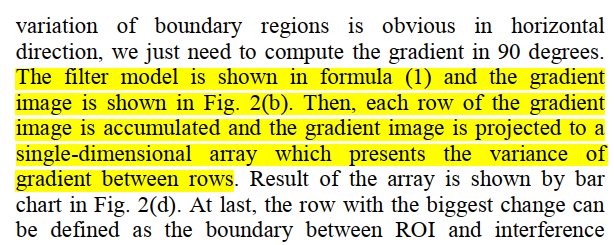

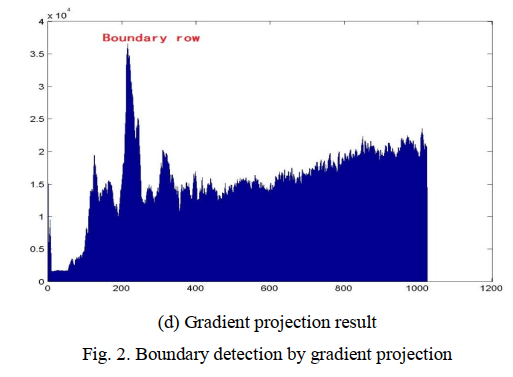

Βρίσκεται σε κάθε εικόνα που έχει εφαρμοστεί η μάσκα αθροίζονται όλα τα στοιχεία κάθε γραμμής και ο πίνακας μετατρέπεται σε έναν μονοδιάστατο πίνακα με στοιχεία τα αθροίσματα των προηγούμενων στηλών. Η γραμμή με to μεγαλύτερο άθροισμα δηλαδή η η γραμμή με δείτη το pixel που συμμετείχε στις περισσότερες ακμές (αφού είχε άσπρα pixel) είναι αυτή στην οποία θα διαχωριστεί η περιοχή ενδιαφέροντος.

ii =1;  
while hasFrame(shuttleAvi)
   mov(ii) = im2frame(readFrame(shuttleAvi));
   mov_sobel(ii)=mov(ii);
   mov_prewitt(ii)=mov(ii);
   
   I1=rgb2gray(mov(ii).cdata);
   
    Gsob=[-1 -2 -1 ; 0 0 0; 1 2 1];    
    Gpre=[-1 -1 -1; 0 0 0; 1 1 1];
    
    [img_sobel_mask{ii},index_sobel_mat(ii)]=algorithm(I1,Gsob);
    [img_prewitt_mask{ii},index_prewitt_mat(ii)]=algorithm(I1,Gpre);

   if ii~=1 %smoothing
       index_sobel_mat(ii)=floor((index_sobel_mat(ii)+index_sobel_mat(ii-1))/2);
       index_prewitt_mat(ii)=floor((index_prewitt_mat(ii)+index_prewitt_mat(ii-1))/2);
   end
   
   mov_sobel(ii).cdata(1:index_sobel_mat(ii),:,:)=0; % apply the mask to every pixel until the index_sobel_mat(ii) position
   mov_prewitt(ii).cdata(1:index_prewitt_mat(ii),:,:)=0; % apply the mask to every pixel until the index_prewitt_mat(ii) position 
   
   ii = ii+1;
end

Παρουσιάζεται ένα  frame του βίντεο της κανονικής εικόνας πειν και μετά την εφαρμογή μάσκας.

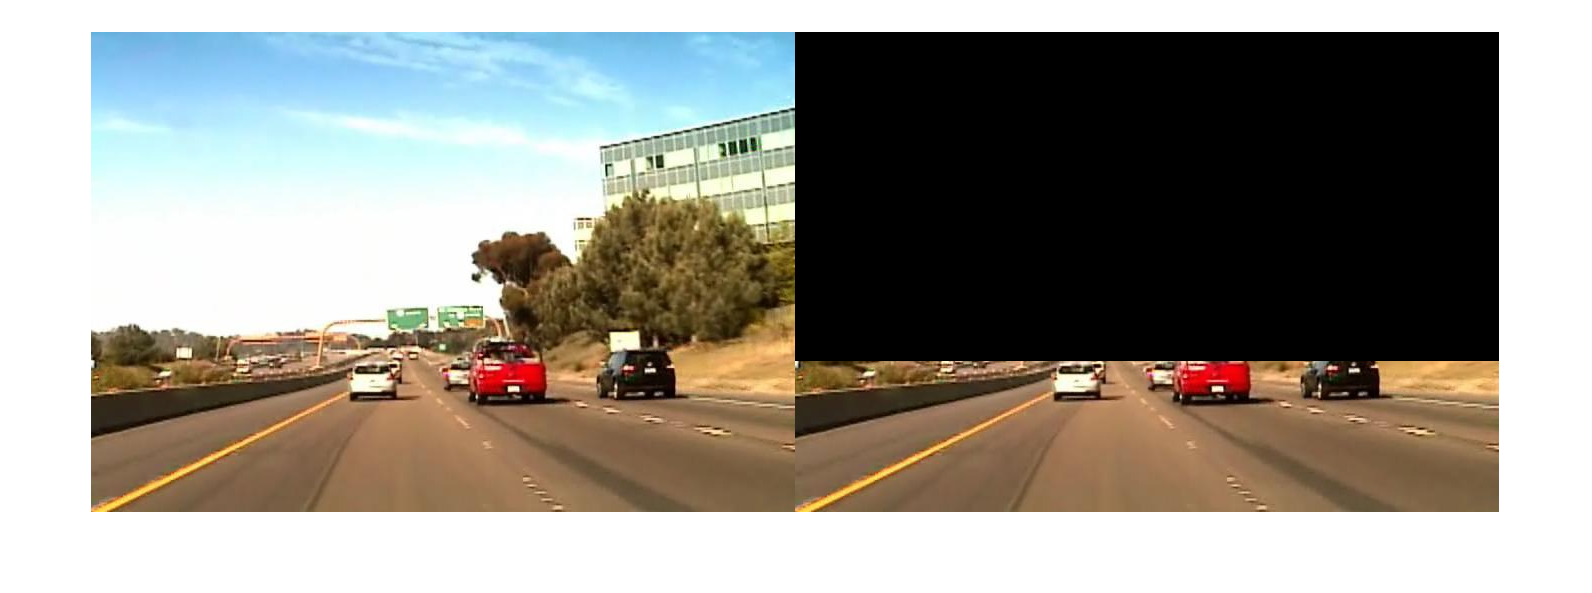

imshowpair(mov(300).cdata,mov_sobel(300).cdata,'montage')

το 1ο frame του βίντεο μετά την εφαρμογή sobel μάσκας και prewitt αντίστοιχα.

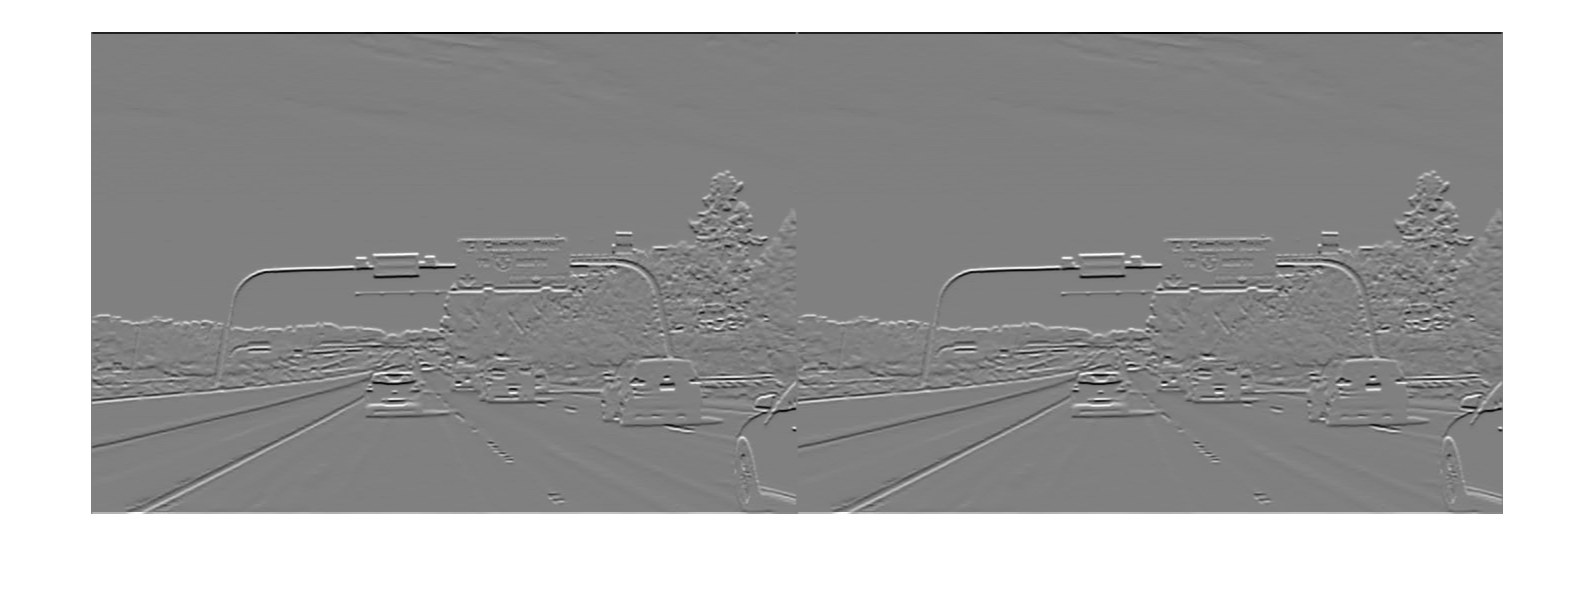

imshowpair(img_sobel_mask{1},img_prewitt_mask{1},'montage')

Το καινούριο βίντεο αρχίζει να παίζει με την παρακάτω εντολή και όπως φαίνεται έχει εφαρμοστεί η μάσκα και πλέον επικεντρώνεται στην περιοχή ενδιαφέροντος

 %movie(mov_prewitt,1,shuttleAvi.FrameRate)
 %movie(mov_sobel,1,shuttleAvi.FrameRate)

ΕΡΩΤΗΜΑ 2) Για το ερώτημα αυτό έχει εφαρμοστεί η ίδια μέθοδος μόνο που σε κάθε frame του βίντεο αφού γίνει ασπρόμαυρο προστίθεται θόρυβος στην μία περίπτωση gaussian ( λευκός)  και στην άλλη salt and pepper (κρουστικός). Έπειτα πάλι βρίσκεται η περιοχή ενδιαφέροντος αλλά όπως παρατηρείται έχει υποβαθμιστεί η ακρίβεια εφαρμογής της περιοχής ενδιαφέροντος καθώς πλέον οι  μάσκες εντοπίζουν και άχρηστη πληροφορία (θόρυβο) στον εντοπισμό ακμών. Η συνάρτηση που χρησιμοποιήθηκε για εφαρμογή θορύβου είναι η imnoise(I1,typeOfNoise)

όπου Ι1η εικόνα που προστίθεται ο θόρυβος και typeOfNoise το είδος του θορύβου.

shuttleAvi = VideoReader(fullfile(workingDir,'shuttle_out.avi'));
ii = 1;
while hasFrame(shuttleAvi)
   mov(ii) = im2frame(readFrame(shuttleAvi));
   
   mov_sobel_gauss(ii)=mov(ii);
   mov_prewitt_gauss(ii)=mov(ii);
   
   mov_sobel_s_p(ii)=mov(ii);
   mov_prewitt_s_p(ii)=mov(ii);
   
   I1=rgb2gray(mov(ii).cdata);
   
    Gsob=[-1 -2 -1 ; 0 0 0; 1 2 1];    
    Gpre=[-1 -1 -1; 0 0 0; 1 1 1];
%working with the noised images======================================>
    I_s_p= imnoise(I1,'salt & pepper');
    I_gauss = imnoise(I1,'gaussian') ;
    

    
    [img_sobel_mask_gauss{ii},index_sobel_mat_gauss(ii)]=algorithm(I_gauss,Gsob);
    [img_prewitt_mask_gauss{ii},index_prewitt_mat_gauss(ii)]=algorithm(I_gauss,Gpre);
    
    [img_sobel_mask_s_p{ii},index_sobel_mat_s_p(ii)]=algorithm(I_s_p,Gsob);
    [img_prewitt_mask_s_p{ii},index_prewitt_mat_s_p(ii)]=algorithm(I_s_p,Gpre);
   
   if ii~=1 %smoothing
       index_sobel_mat_gauss(ii)=floor((index_sobel_mat_gauss(ii)+index_sobel_mat_gauss(ii-1))/2);
       index_prewitt_mat_gauss(ii)=floor((index_prewitt_mat_gauss(ii)+index_prewitt_mat_gauss(ii-1))/2);
   end
   
   if ii~=1 %smoothing
       index_sobel_mat_s_p(ii)=floor((index_sobel_mat_s_p(ii)+index_sobel_mat_s_p(ii-1))/2);
       index_prewitt_mat_s_p(ii)=floor((index_prewitt_mat_s_p(ii)+index_prewitt_mat_s_p(ii-1))/2);
   end
   
   mov_sobel_s_p(ii).cdata(1:index_sobel_mat_s_p(ii),:,:)=0; % apply the mask to every pixel until the index_sobel_mat(ii) position
   mov_prewitt_s_p(ii).cdata(1:index_prewitt_mat_s_p(ii),:,:)=0; % apply the mask to every pixel until the index_prewitt_mat(ii) position
   
   mov_sobel_gauss(ii).cdata(1:index_sobel_mat_gauss(ii),:,:)=0; % apply the mask to every pixel until the index_sobel_mat(ii) position
   mov_prewitt_gauss(ii).cdata(1:index_prewitt_mat_gauss(ii),:,:)=0; % apply the mask to every pixel until the index_prewitt_mat(ii) position

Εδώ ακολουθείται η ίδια διαδικασία του αλγορίθμου απλώς εφαρμόζεται στην ακολουθία εικόνων που αφού τους είχε προστεθεί ο θόρυβος τώρα αφαιρείται με median filter 

%working with the denoised images======================================>

   mov_sobel_gauss_denoised(ii)=mov(ii);
   mov_prewitt_gauss_denoised(ii)=mov(ii);
   
   mov_sobel_s_p_denoised(ii)=mov(ii);
   mov_prewitt_s_p_denoised(ii)=mov(ii);
   
   I_s_p_denoised= medfilt2(I_s_p);
   I_gauss_denoised=medfilt2(I_gauss);
    
   [img_sobel_mask_gauss_denoised{ii},index_sobel_mat_gauss_denoised(ii)]=algorithm(I_gauss_denoised,Gsob);
   [img_prewitt_mask_gauss_denoised{ii},index_prewitt_mat_gauss_denoised(ii)]=algorithm(I_gauss_denoised,Gpre);
    
   [img_sobel_mask_s_p_denoised{ii},index_sobel_mat_s_p_denoised(ii)]=algorithm(I_s_p_denoised,Gsob);
   [img_prewitt_mask_s_p_denoised{ii},index_prewitt_mat_s_p_denoised(ii)]=algorithm(I_s_p_denoised,Gpre); 
    if ii~=1 %smoothing
       index_sobel_mat_gauss_denoised(ii)=floor((index_sobel_mat_gauss_denoised(ii)+index_sobel_mat_gauss_denoised(ii-1))/2);
       index_prewitt_mat_gauss_denoised(ii)=floor((index_prewitt_mat_gauss_denoised(ii)+index_prewitt_mat_gauss_denoised(ii-1))/2);
   end
   
   if ii~=1 %smoothing
       index_sobel_mat_s_p_denoised(ii)=floor((index_sobel_mat_s_p_denoised(ii)+index_sobel_mat_s_p_denoised(ii-1))/2);
       index_prewitt_mat_s_p_denoised(ii)=floor((index_prewitt_mat_s_p_denoised(ii)+index_prewitt_mat_s_p_denoised(ii-1))/2);
   end
   
   mov_sobel_s_p_denoised(ii).cdata(1:index_sobel_mat_s_p_denoised(ii),:,:)=0;
   mov_prewitt_s_p_denoised(ii).cdata(1:index_prewitt_mat_s_p_denoised(ii),:,:)=0; 
   
   mov_sobel_gauss_denoised(ii).cdata(1:index_sobel_mat_gauss_denoised(ii),:,:)=0; 
   mov_prewitt_gauss_denoised(ii).cdata(1:index_prewitt_mat_gauss_denoised(ii),:,:)=0; 
   
   ii = ii+1;
end

Παρακάτω είναι ο κώδικας που εμφανίζει 4 γραφήματα. Κάθε γράφημα περιέχει 3 διαφορετικές συναρτήσειςς με τον άξονα  χ να έχει τα 300 pixels στα οποία τα 300 frames έχουν την οριακή γραμμή που εφαρμόζεται το ROI και τον y τις τιμές των pixels αυτών. ΟΙ 3 διαφορετικές ακολουθίες εικόνων στις οποίες εφαρμόζεται ο αλγόριθμος είναι :**με μαύρο** είναι το βίντεο χωρίς θόρυβο , **με κίτρινο** το βίντεο με θόρυβο , **με κόκκινο** το βίντεο αφότου αφαιρέθηκε ο θόρυβος με την median filter.

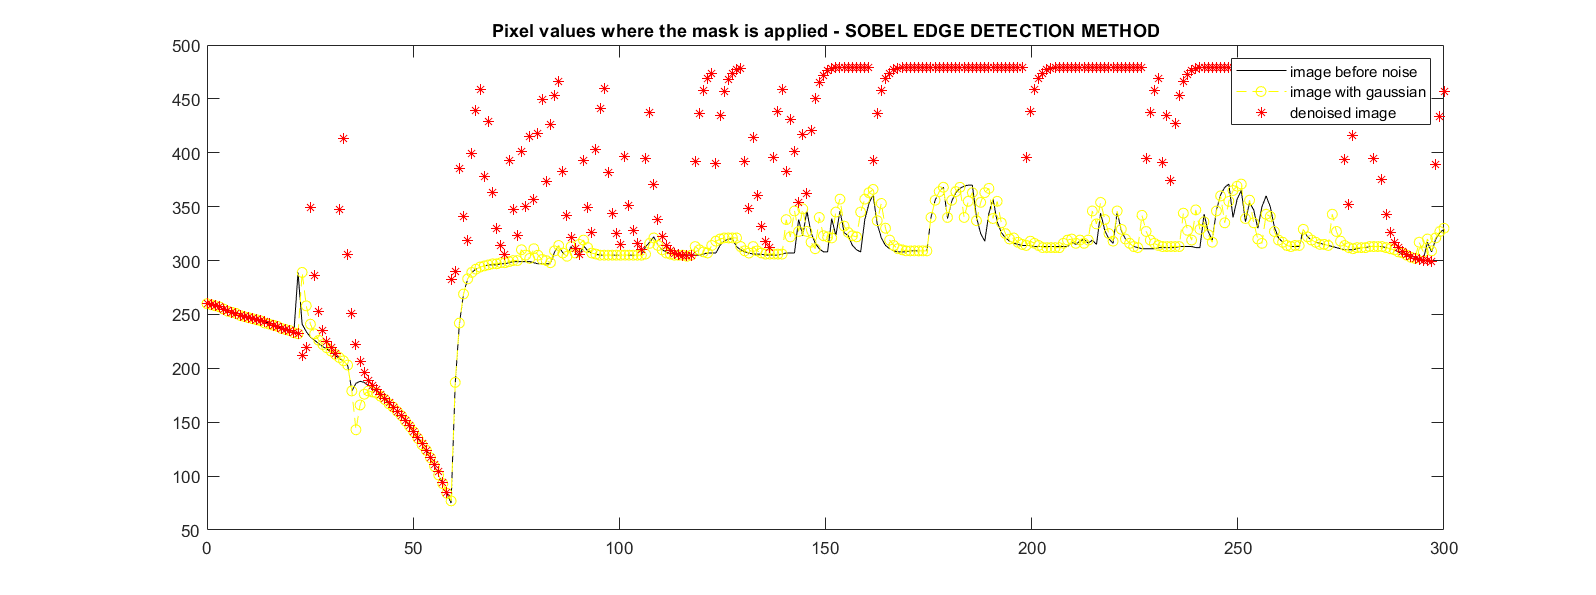

x=linspace(0,300,300);
plot(x,index_sobel_mat,'k',x,index_sobel_mat_gauss,'y--o',x,index_sobel_mat_gauss_denoised,'r*')
title('Pixel values where the mask is applied - SOBEL EDGE DETECTION METHOD')
legend('image before noise','image with gaussian','denoised image' )

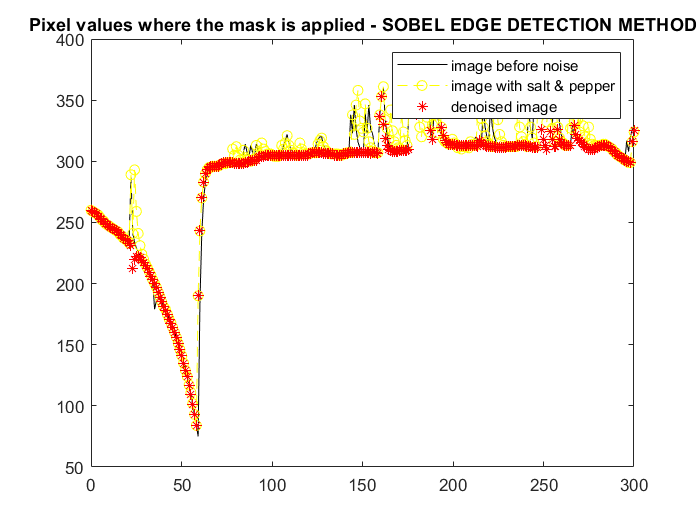


figure()
plot(x,index_sobel_mat,'k',x,index_sobel_mat_s_p,'y--o',x,index_sobel_mat_s_p_denoised,'r*')
title('Pixel values where the mask is applied - SOBEL EDGE DETECTION METHOD')
legend('image before noise','image with salt & pepper','denoised image' )

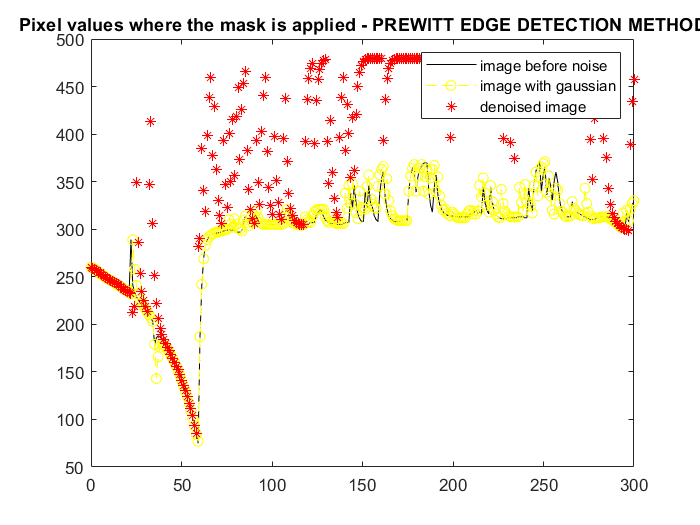


figure()
plot(x,index_prewitt_mat,'k',x,index_prewitt_mat_gauss,'y--o',x,index_prewitt_mat_gauss_denoised,'r*')
title('Pixel values where the mask is applied - PREWITT EDGE DETECTION METHOD')
legend('image before noise','image with gaussian','denoised image' )

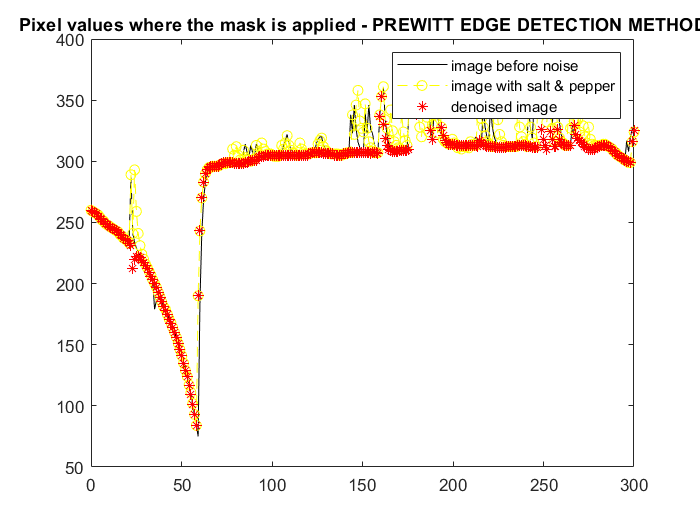


figure()
plot(x,index_prewitt_mat,'k',x,index_prewitt_mat_s_p,'y--o',x,index_prewitt_mat_s_p_denoised,'r*')
title('Pixel values where the mask is applied - PREWITT EDGE DETECTION METHOD')
legend('image before noise','image with salt & pepper','denoised image' )

### Συμπεράσματα : 

'Οπως φαίνεται στις γραφικές ο θόρυβος επηρεάζει και χειροτερέυει  την περιοχή ενδιαφέροντος καθώς έχει εισάγει και άλλες συνιστώσες στην εικόνα που μετά την εφαρμογή μασκών προκύπτουν άχρηστες ακμές. 

Βλέπουμε παρότι εφαρμόζεται median φιλτρο για απομάκρυνση του θορύβου που είναι αποδοτικό για την απομάκρυσνη gaussian και salt and pepper θορυβου, φαινεται οτι η denoised εικόνα που σε αυτή έχει εφαρμοιστεί Gaussian Noise  αποκλίνει περισσότερο από κάθε άλλη περίπτωση απο την αρχική  κάτι το οποίο γίνεται αντιληπτό από τις γραφικές που βρίσκονται παραπάνω οι οποίες δείχνουν την μεταβολή που έχουν τα pixels.

**ΕΡΩΤΗΜΑ 3)**

Για το ερώτημα αυτό χρησιμοποιείται ένα  Canny edge detection φιλτρο ώστε να κάνουμε δυαδικό τον πίνακα που θα παίρνει ως όρισμα ο μετασχηματισμός hough. Eφαρμόζουμε μετασχηματισμό σε κάθε frame του βίντεο και ύστερα από αυτόν προκύπτει ο πίνακας lines ο οποίος μας δίνει τις συντενταγμένες των κύριων ευθειών καθώς και τις γωνίες που σχηματίζουν. Έτσι, σύμφωνα με τα δεδομένα αυτά βρήκαμε τις κύριες γραμμές σε κάθε frame και συγκεκριμενοποιήσαμε και άλλο το ROI αφού κόψαμε τα pixels που βρίσκονται πάνω από τις κύριες γραμμές, δηλαδή πετύγχαμε lane detection . Ύστερα, στην νέα περιοχή ενδιφέροντος εφαρμόσαμε Otsu Thresholing το οποίο συγκρίνει το backround με το foreground της εικόνας και βρίσκει ένα κατώφλι που σύμφωνα με αυτό κρατάει την χρήσιμη πληροφορία.Το threshold είναι πολύ σημαντικό και βρίσκεται με αλγοριθμικό μαθηματικό τρόπο .

Παρακάτω φαίνεται ένα παράδειγμα για 6 μόνο τιμές grayscale κλίμακας.

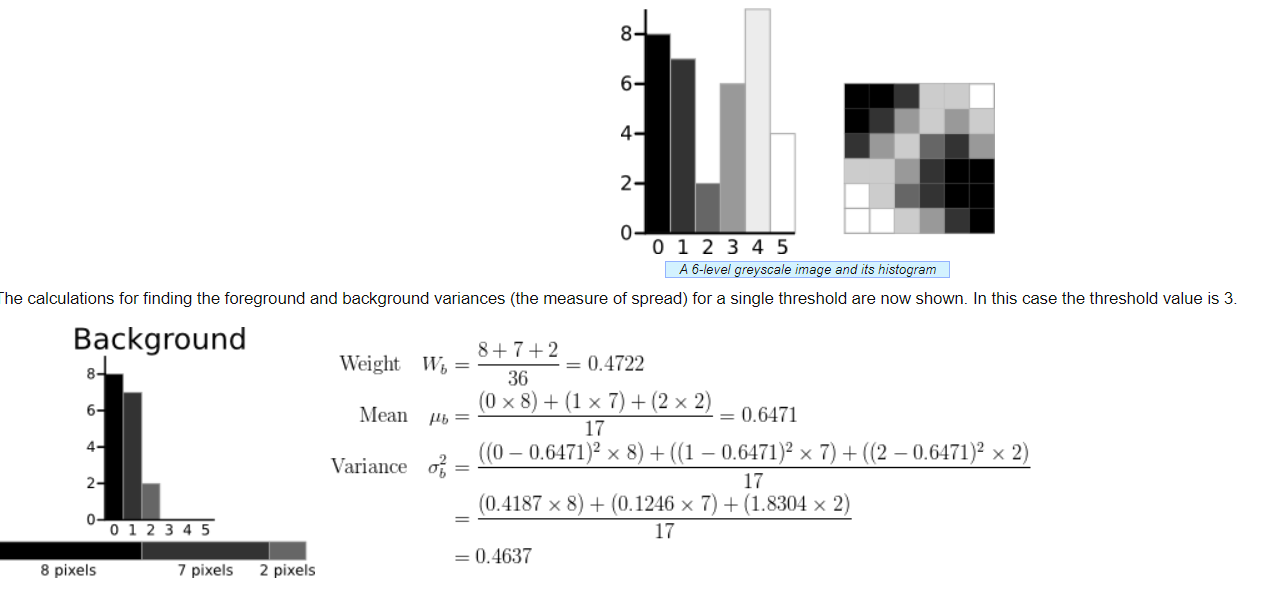  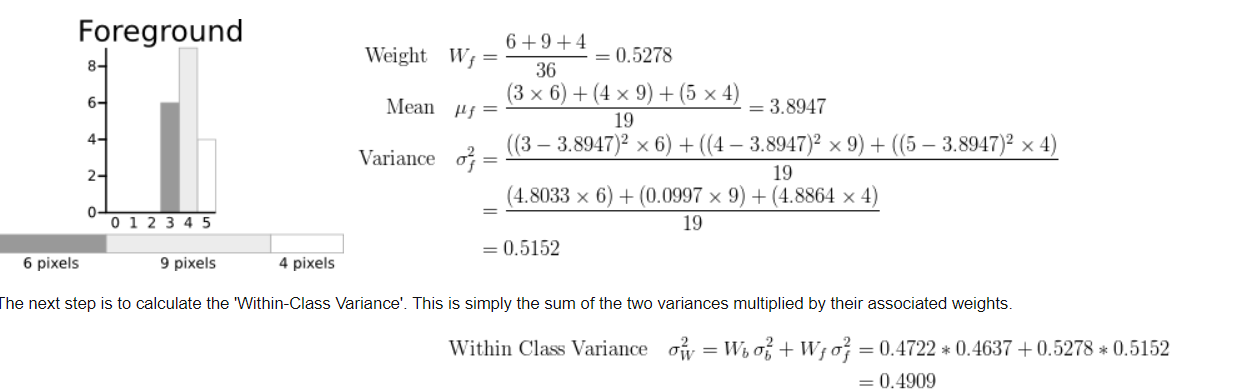

Τέλος εφαρμόζεται ξανά sobel φιλτρο στο τελικό αποτέλεσμα της εικόνας 

shuttleAvi = VideoReader(fullfile(workingDir,'shuttle_out.avi'));
ii =1;  
H={};
T={};
R={};
lines={};
after_otsu={};
while hasFrame(shuttleAvi)
   mov(ii) = im2frame(readFrame(shuttleAvi));
   mov_sobel(ii)=mov(ii);
   mov_prewitt(ii)=mov(ii);
   
   I1=rgb2gray(mov(ii).cdata);
   
    Gsob=[-1 -2 -1 ; 0 0 0; 1 2 1];    
    Gpre=[-1 -1 -1; 0 0 0; 1 1 1];
    
    [img_sobel_mask{ii},index_sobel_mat(ii)]=algorithm(I1,Gsob);
    [img_prewitt_mask{ii},index_prewitt_mat(ii)]=algorithm(I1,Gpre);

   if ii~=1 %smoothing
       index_sobel_mat(ii)=floor((index_sobel_mat(ii)+index_sobel_mat(ii-1))/2);
       index_prewitt_mat(ii)=floor((index_prewitt_mat(ii)+index_prewitt_mat(ii-1))/2);
   end
   
   mov_sobel(ii).cdata(1:index_sobel_mat(ii),:,:)=0; % apply the mask to every pixel until the index_sobel_mat(ii) position
   mov_prewitt(ii).cdata(1:index_prewitt_mat(ii),:,:)=0; % apply the mask to every pixel until the index_prewitt_mat(ii) position 
   
   canny_image{ii}=rgb2gray(mov_sobel(ii).cdata);
   canny_image{ii}=edge(canny_image{ii},'Canny','both');
   [H1,T1,R1,lines1]=hough_alg(mov_sobel(ii).cdata,canny_image{ii});
   H{ii}=H1;
   T{ii}=T1;
   R{ii}=R1;
   lines{ii}=lines1;
   if length(lines{ii})>2
      mov_sobel(ii).cdata=apply_new_mask_lane(mov_sobel(ii).cdata,lines{ii});
   else
      mov_sobel(ii).cdata= mov_sobel(ii-1).cdata;
      
   end
   after_otsu{ii}=otsu_alg(mov_sobel(ii).cdata);
   after_otsu{ii}=edge(after_otsu{ii},'Sobel',"both");
   ii = ii+1;
end

εδώ φαίνεται ένα frame με την εφαρμογή της καινούριας ROI μετά το lane detection

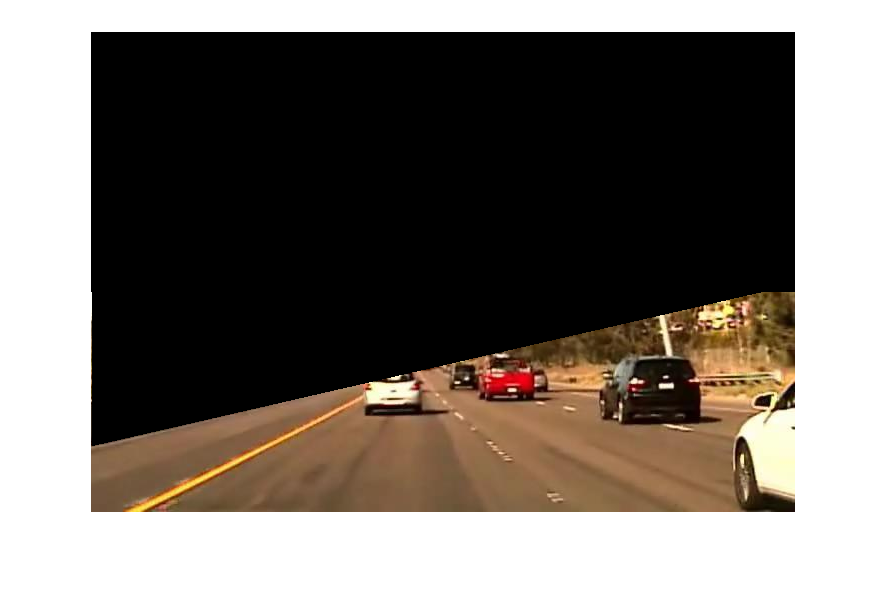

imshow(mov_sobel(1).cdata)

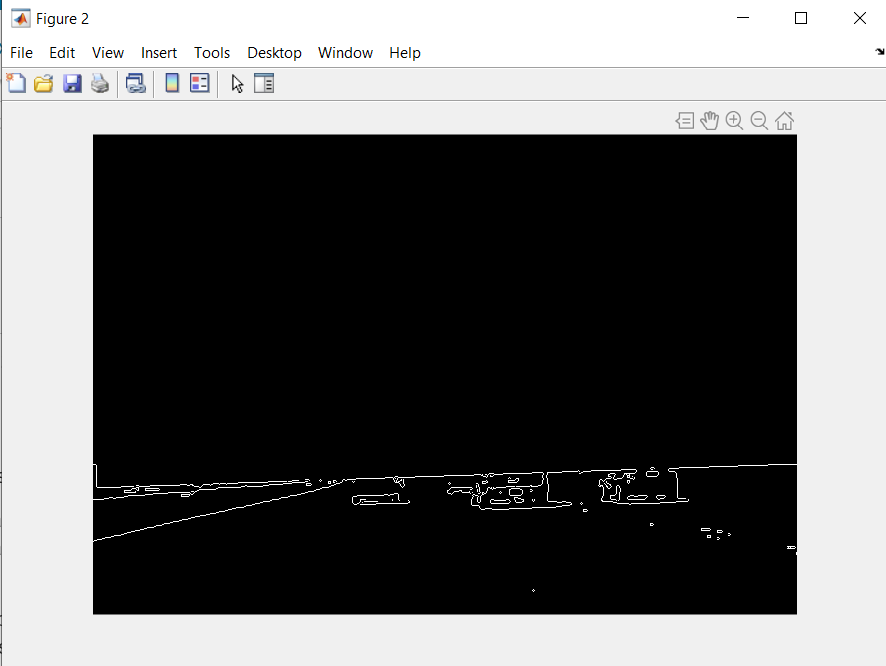

ΣΥΝΑΡΤΗΣΕΙΣ ΠΟΥ ΔΗΜΙΟΥΡΓΗΘΗΚΑΝ 

παρακάτω φαίνεται η συνάρτηση algorithm όπου υπολογίζει την περιοχή ενδιαφέροντος μέσω συνελίξεων  με τις μάσκες  sobel  και prewitt.Κρατάμε που βρέθηκε η γραμμή με το μεγαλύτερο άθροισμα και το index της επιστρέφεται και είναι εκεί που θα τελείωνει η ROI

function [pinakas,index_pinaka]=algorithm(image,filter)
   
   pinakas=conv2(image,filter);
   for rows=1:size(pinakas,1)-2
       sums_filter(rows)=sum(pinakas(rows,:));  
   end
   [max_pinaka,index_pinaka]=max(sums_filter);
end


H συνάρτηση που υλοποιεί τον αλγόριθμι hough  και βρίσκει τις γραμμές ώστε να γίνει το lane detection και να περιοριστεί και άλλο η εικόνα 

function [H,T,R,lines]=hough_alg(rgb_image_with_mask,canny_matrix)
    
    [rcc ccc]=size(rgb_image_with_mask);
    [H,T,R] = hough(canny_matrix);
    
    P= houghpeaks(H,3,'threshold',ceil(0.5*max(H(:))));
    x = T(P(:,2)); y = R(P(:,1));
    lines=houghlines(canny_matrix,T,R,P,'FillGap',0.8*rcc,'MinLength',30);
end




Συνάρτηση για κα΄λυτερη αναπράσταση του μετασχηματισμού hough καθών και των πράσινων γραμμών που αναγνωρίζονται ως κυριότερες.


function plot_with_houghlines(gray_image,rgb_image,canny_matrix,H,T,R,lines)
    [rcc ccc]=size(gray_image);
    imshow(canny_matrix)
    figure()
    imshow(H,[],'XData',T,'YData',R,...
                'InitialMagnification','fit');
    xlabel('\theta'), ylabel('\rho');
    axis on, axis normal, hold on;
    P  = houghpeaks(H,3,'threshold',ceil(0.5*max(H(:))));
    x = T(P(:,2)); y = R(P(:,1));
    plot(x,y,'s','color','white');
    figure(),imshow(rgb_image),hold on
    for k = 1:length(lines)
       xy = [lines(k).point1; lines(k).point2];
       plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
       hold on
    end
end


Mε την παρακάτω συνάρτηση εντοπίζεται και μαυρίζεται το διάστημα που βρίσκεται ανάμεσα από την ευθέια που βρίσκεται εκτός των λωρίδων του δρόμου δηλαδή περιορίζεται η ROI. Για να γίνει αυτό ελέγχουμε τις γωνίες των γραμμών  από κάθε frame και οι κατάλληλες κάθε φορα θα ορίσουν το διάστημα που απορρίπτουμε.

function rgb_image=apply_new_mask_lane(rgb_image,lines)
    thetas=[];
    warning off
    for p=1:3
        thetas=[thetas lines(p).theta];
        if lines(p).theta==-90
        hor_idx=p;
        end
    end
    [max_theta,ang_idx]=max(thetas);
    if ang_idx==hor_idx
        ang_idx=77;
    end
    
    a=(lines(ang_idx).point2(2)-lines(ang_idx).point1(2))/(lines(ang_idx).point2(1)-lines(ang_idx).point1(1));
    b=lines(ang_idx).point2(2)-a*lines(ang_idx).point2(1);
    low_idx=lines
    
    
    
    
    
    
    (ang_idx).point1(1);
    
    for i=floor(lines(hor_idx).point1(2)):floor(lines(ang_idx).point1(2))
        up_idx=floor(i-b)/a;
        rgb_image(i,low_idx:up_idx,:)=0;
    end
    
end

η συνάρτηση για υλοποίση του otsu που πάρθηκε από την mathworks της matlab

function [BW]=otsu_alg(rgb_img)
    I=rgb2gray(rgb_img);
    level = graythresh(I);
    BW = imbinarize(I,level);
end
